clc; clear; close all
rng("default")

# Load 1D-FC Data

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5))

f = function_handle with value:
    @(x,y)4+(1+x.^2+y.^2).*(sin(2.5*pi*x-0.5)+cos(2*pi*y-0.5))


l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

C = 27;
d = 6;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

# Constructing Boundary Patch

## C2 Patch

Needs l(theta) data, the corners on the boundary in terms of theta, and function values on mesh

n_C2 = 20;
n_S_h = 20;
h_S = 0.027;

C2_patch = construct_C2_patch(f, 0.4, 2*pi-0.4, 0, n_C2, n_C2); % data associated with patch

[X, Y] = C2_patch.xy_mesh();
figure;
scatter(X(:), Y(:));
hold on;

## S Patch

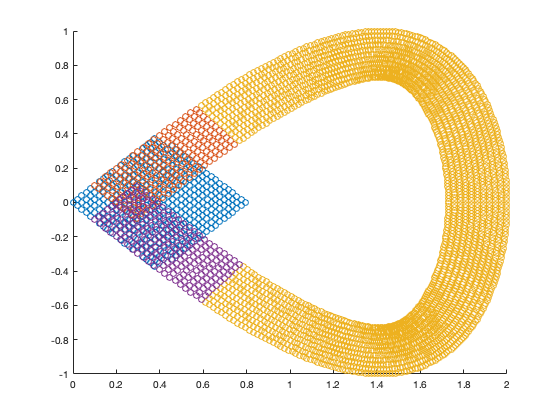

window_patch_xi = construct_S_patch(f, 0.1, 0.6, h_S, n_S_h, 10);
window_patch_eta = construct_S_patch(f, 2*pi-0.1, 2*pi-0.6, h_S, n_S_h, 10);
S_patch = construct_S_patch(f, 0.6, 2*pi-0.6, h_S, 255, 10);

[X, Y] = window_patch_eta.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = S_patch.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = window_patch_xi.xy_mesh();
scatter(X(:), Y(:))

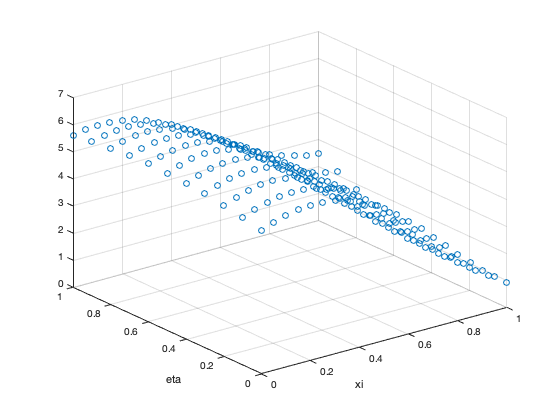


[C2_norm, xi_norm, eta_norm] = C2_patch.compute_phi_normalization(window_patch_xi, window_patch_eta);

[XI, ETA] = window_patch_eta.xi_eta_mesh();
phi_normalized = window_patch_eta.f_XY;%.*window_patch_eta.window_phi(XI, ETA)./eta_norm;
figure;
scatter3(XI(:), ETA(:), phi_normalized(:))
xlabel('xi')
ylabel('eta')

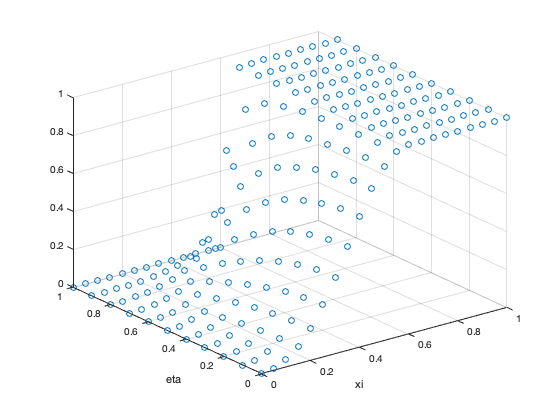


[XI, ETA] = window_patch_eta.xi_eta_mesh();
phi_normalized = window_patch_eta.window_phi(XI, ETA)./eta_norm;
figure;
scatter3(XI(:), ETA(:), phi_normalized(:))
xlabel('xi')
ylabel('eta')

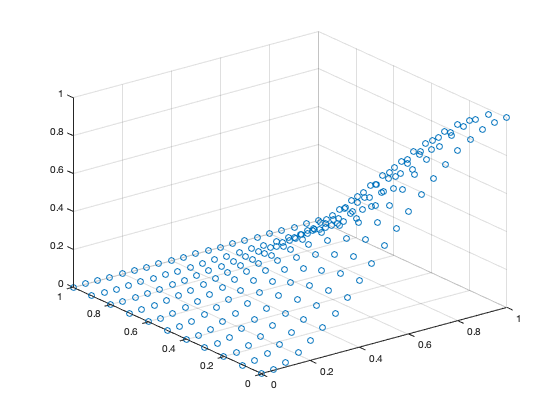


figure;
scatter3(XI(:), ETA(:), window_patch_eta.window_phi(XI(:), ETA(:)))


phi_normalized(1, 1)

ans =      0


window_patch_eta.M_p(0, 0)

ans =      9.995833854135655e-02     9.983341664682804e-02


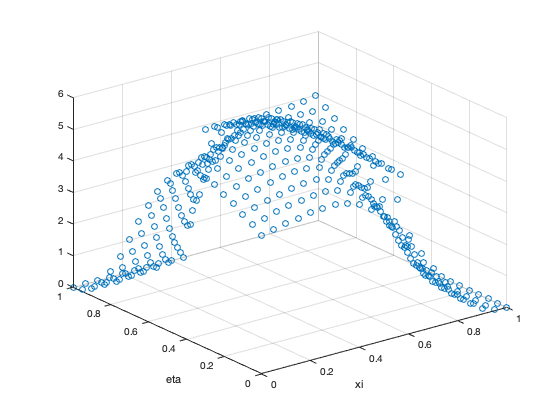


[XI, ETA] = C2_patch.xi_eta_mesh();
phi_normalized = C2_patch.f_XY .* C2_patch.phi(XI, ETA)./C2_norm;
figure;
scatter3(XI(:), ETA(:), phi_normalized(:))
xlabel('xi')
ylabel('eta')


% [XI, ETA] = C2_patch.xi_eta_mesh();
% normalized_phi = C2_patch.phi(XI, ETA)./C2_norm;
% 
% figure;
% scatter3(XI(:), ETA(:), normalized_phi(:))
% xlabel("xi")
% ylabel("eta")
% 
% 
% figure;
% [XI, ETA] = window_patch_eta.xi_eta_mesh();
% normalized_phi = window_patch_eta.window_phi(XI, ETA)./xi_norm;
% figure;
% scatter3(XI(:), ETA(:), normalized_phi(:))

% [XI, ETA] = C2_patch.xi_eta_mesh();
% phi_normalized = C2_patch.phi(XI, ETA)./C2_norm;
% C2_patch.f_XY = phi_normalized;
% 
% figure;
% scatter3(XI(:), ETA(:), C2_patch.f_XY(:))
% 
% [XI, ETA] = window_patch_xi.xi_eta_mesh();
% phi_normalized = window_patch_xi.window_phi(XI, ETA)./xi_norm;
% window_patch_xi.f_XY = phi_normalized;
% 
% figure;
% scatter3(XI(:), ETA(:), window_patch_xi.f_XY(:))
% 
% [XI, ETA] = window_patch_eta.xi_eta_mesh();
% phi_normalized = window_patch_eta.window_phi(XI, ETA)./eta_norm;
% window_patch_eta.f_XY = phi_normalized;
% 
% figure;
% scatter3(XI(:), ETA(:), window_patch_eta.f_XY(:))
% 
% % x = 0.390195939203193;
% % y = 0.382286945452236;
% 
% v = window_patch_eta.M_p(0.5, 1)
% x = v(1)
% y = v(2)
% 
% [xi, eta, converged] = C2_patch.inverse_M_p(x, y)
% phi_1 = C2_patch.phi(xi, eta)
% 
% % [phi_1, ~, in_range] = C2_patch.locally_compute(x, y, 9);
% % [phi_2, ~, ~] = window_patch_eta.locally_compute(x, y, 9);
% phi_2 = window_patch_eta.window_phi(0.5, 1)
% 
% phi_1 + phi_2 - eta_norm(11, 11)
% eta_norm(11, 11)

# FC on C2 Patch and S Patch

Assumes we know what type the patches are, if not, we can simply add another entry that is enumeration of the patch types

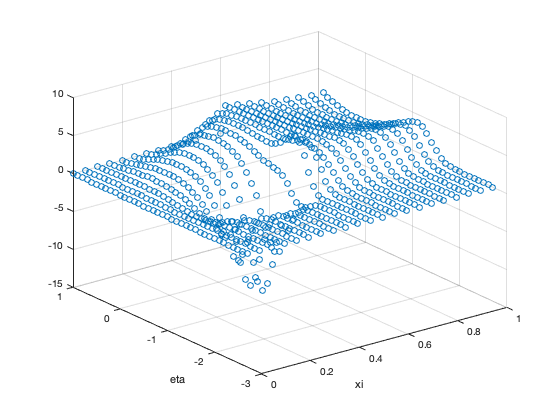

% creates patch with data, including partition of unity
C2_fcont_patch = C2_patch.FC(C, d, A, Q, C2_norm);
window_fcont_patch_xi = window_patch_xi.FC(C, d, A, Q, xi_norm);
window_fcont_patch_eta = window_patch_eta.FC(C, d, A, Q, eta_norm);
S_fcont_patch = S_patch.FC(C, d, A, Q, nan);

[XI, ETA] = window_fcont_patch_eta.xi_eta_mesh();
figure;
scatter3(XI(:), ETA(:), window_fcont_patch_eta.f_XY(:))
xlabel("xi")
ylabel("eta")

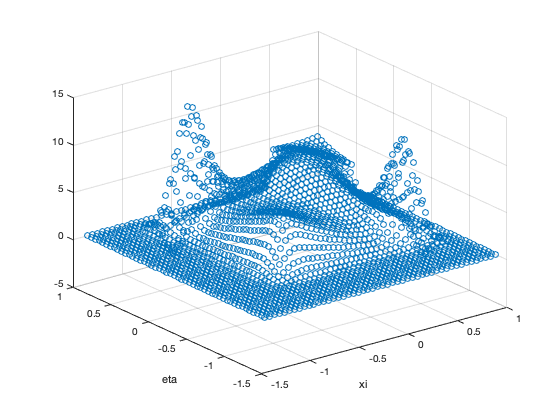


[XI, ETA] = C2_fcont_patch.xi_eta_mesh();
figure;
scatter3(XI(:), ETA(:), C2_fcont_patch.f_XY(:))
xlabel("xi")
ylabel("eta")

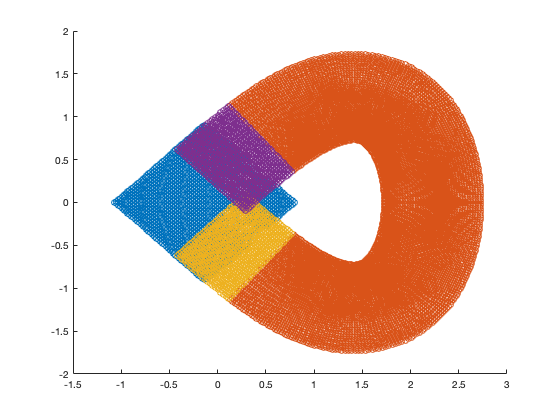


[X_C2, Y_C2] = C2_fcont_patch.xy_mesh();
[X_S, Y_S] = S_fcont_patch.xy_mesh();
[X_xi, Y_xi] = window_fcont_patch_xi.xy_mesh();
[X_eta, Y_eta] = window_fcont_patch_eta.xy_mesh();
figure;
scatter(X_C2(:), Y_C2(:));
hold on;
scatter(X_S(:), Y_S(:));
scatter(X_xi(:), Y_xi(:));
scatter(X_eta(:), Y_eta(:));

# Interpolation onto R

Note that we don't have any interior patches, so if any points aren't in the C2 or S patch, we just assume we know the value.

R_x_bounds = [C2_fcont_patch.x_min, S_fcont_patch.x_max];
R_y_bounds = [S_fcont_patch.y_min, S_fcont_patch.y_max];

n_R = 80;
h_R_x = (R_x_bounds(2) - R_x_bounds(1))/n_R

h_R_x =      4.744864822772358e-02


h_R_y = (R_y_bounds(2) - R_y_bounds(1))/n_R

h_R_y =      4.322390011201552e-02



[R_X, R_Y] = meshgrid(linspace(R_x_bounds(1), R_x_bounds(2), n_R+1), linspace(R_y_bounds(1), R_y_bounds(2), n_R+1));
f_R = zeros(size(R_X));

theta_mesh = transpose(linspace(0, 2*pi, 100));
boundary_XY = l_theta(theta_mesh);
interior_polygon = inpolygon(R_X, R_Y, boundary_XY(:, 1), boundary_XY(:, 2));

range_msk = logical(zeros(size(R_X)));

for i = 1:size(R_X, 1)
    for j = 1:size(R_X, 2)
        x = R_X(i, j);
        y = R_Y(i, j);
        
        if interior_polygon(i, j)
             f_R(i, j) = f(x, y);
        else
            [f_S, ~, in_range_S] = S_fcont_patch.locally_compute(x, y, d+1);            
            if in_range_S
                f_R(i, j) = f_S;
            else
                [f_C2, ~, in_range_C2] = C2_fcont_patch.locally_compute(x, y, d+1);
                [f_window_xi, ~, in_range_xi] = window_fcont_patch_xi.locally_compute(x, y, d+1);
                [f_window_eta, ~, in_range_eta] = window_fcont_patch_eta.locally_compute(x, y, d+1);
                
                if in_range_C2
                    f_R(i, j) = f_R(i, j) + f_C2;
                end
                if in_range_xi
                    f_R(i, j) = f_R(i, j) + f_window_xi;
                end
                if in_range_eta
                    f_R(i, j) = f_R(i, j) + f_window_eta;
                end
                
                if ~in_range_C2 & ~in_range_xi & ~in_range_eta
                    range_msk(i, j) = true;
                end
            end
        end
    end
end

[XI, ETA] = S_patch.xi_eta_mesh();

f_R_XY = f(R_X, R_Y);
figure;
scatter3(R_X(interior_polygon), R_Y(interior_polygon), f_R_XY(interior_polygon))
figure;
scatter3(R_X(:), R_Y(:), f_R(:))
xlabel("x")
ylabel('y')

figure;
scatter(R_Y(:, 28), f_R(:, 28))

figure;
scatter(R_X(range_msk), R_Y(range_msk))
hold on;
plot(boundary_XY(:, 1), boundary_XY(:, 2))

figure;
scatter3(R_X(:), R_Y(:), f_R(:))

cross_X = R_Y(:, 42);
cross_Y = f_R(:, 42);

fc_coeffs = fft(cross_Y)/numel(cross_Y);

n_cont = length(cross_Y);
n_err = n_cont*5;

h_cont = (cross_X(end) - cross_X(1))/(n_cont-1);

x_err_mesh = transpose(linspace(cross_X(1), cross_X(end)+h_cont, n_err+1));
x_err_mesh = x_err_mesh(1:end-1);

shift_vector = exp(-1i*2*pi*(floor(n_cont/2))*transpose(0:(n_err-1))/n_err);
fcont_numeric = real(n_err*ifft(fftshift(fc_coeffs), n_err).*shift_vector);

figure;
scatter(x_err_mesh, fcont_numeric)
hold on;
plot(cross_X, cross_Y)

% x = 0.202037574753139;
% Y = [0.219535297222709, 0.202648]; %, 0.185761, 0.219535, 0.236423];
% figure;
% scatter(cross_X, cross_Y)
% 
% [XI, ETA] = window_patch_eta.xi_eta_mesh();
% figure;
% scatter(XI(:), ETA(:));
% hold on;
% for y = Y
%     [XI_window, ETA_window, converged] = window_patch_eta.inverse_M_p(x, y)    
% 
%     scatter(XI_window, ETA_window)
% end
% 
% C2_patch.phi(0, 0.5)
% 
% [XI, ETA] = C2_patch.xi_eta_mesh();
% figure;
% scatter(XI(:), ETA(:));
% hold on;
% 
% for y = Y
%     [XI_C2, ETA_C2, converged] = C2_patch.inverse_M_p(x, y)
% 
%     scatter(XI_C2, ETA_C2)
% end

% 
% fc_coeffs = fft(cross_Y)./numel(cross_Y)
% 
% n_R_err = n_R * 10;
% 
% R_y_err_mesh = linspace(cross_X(1), cross_X(2)+h_R_y, n_R_err+1);
% R_y_err_mesh = R_y_err_mesh(1:end-1);
% 
% 
% Q_shift = 0:(n_R_err-1)
% shift_matrix = exp(-2i*pi*floor((n_R+1)/2)*Q_shift/(n_R_err))
% f_numeric = real(n_R_err*ifft(fftshift(fc_coeffs), n_R_err).*shift_matrix)
% 
% 
% figure;
% plot(err_mesh, f_numeric)

# FFT

fc_coeffs = fft2(f_R)./numel(f_R)

n_x = size(fc_coeffs, 2);
n_y = size(fc_coeffs, 1);
[Q_shift, P_shift] = meshgrid(0:n_x-1, 0:n_y-1);
shift_matrix = exp(-2i*pi*floor(n_y/2)*P_shift/n_y) .* exp(-2i*pi*floor(n_x/2)*Q_shift/n_x)
f_numeric = real((n_x*n_y)*ifft2(fftshift(fc_coeffs), n_y, n_x).*shift_matrix)

figure;
scatter3(R_X(interior_polygon), R_Y(interior_polygon), f_numeric(interior_polygon))
n_R_err = 10*n_R + 1;

max(abs(f_numeric(interior_polygon) - f(R_X(interior_polygon), R_Y(interior_polygon))))

R_x_err_mesh = linspace(R_x_bounds(1), R_x_bounds(2)+h_R_x, n_R_err+1);
R_x_err_mesh = R_x_err_mesh(1:end-1);
R_y_err_mesh = linspace(R_y_bounds(1), R_y_bounds(2)+h_R_y, n_R_err+1);
R_y_err_mesh = R_y_err_mesh(1:end-1);

[R_X_err, R_Y_err] = meshgrid(R_x_err_mesh, R_y_err_mesh);
interior_polygon_err = inpolygon(R_X_err, R_Y_err, boundary_XY(:, 1), boundary_XY(:, 2))

[Q_shift, P_shift] = meshgrid(0:n_R_err-1);
shift_matrix = exp(-2i*pi*floor((n_R+1)/2)*P_shift/(n_R_err)) .* exp(-2i*pi*floor((n_R+1)/2)*Q_shift/(n_R_err))
f_numeric = real(((n_R_err)^2)*ifft2(fftshift(fc_coeffs), n_R_err, n_R_err).*shift_matrix)
f_exact = f(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err));

figure;
scatter3(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err), abs(f_exact-f_numeric(interior_polygon_err)))

f_exact = f(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err));
max(abs(f_exact-f_numeric(interior_polygon_err)))

err = abs(f_exact-f_numeric(interior_polygon_err))
norm_err = err./max(err)

figure;
scatter(R_X_err(interior_polygon_err), R_Y_err(interior_polygon_err), 100, norm_err, 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

cross_X = R_Y(:, 28);
cross_Y = f_R(:, 28);

fc_coeffs = fft(cross_Y)/numel(cross_Y);

n_cont = length(cross_Y);
n_err = n_cont*3;

h_cont = (cross_X(end) - cross_X(1))/(n_cont-1);

x_err_mesh = transpose(linspace(cross_X(1), cross_X(end)+h_cont, n_err+1));
x_err_mesh = x_err_mesh(1:end-1);

shift_vector = exp(-1i*2*pi*(floor(n_cont/2))*transpose(0:(n_err-1))/n_err);
fcont_numeric = real(n_err*ifft(fftshift(fc_coeffs), n_err).*shift_vector);

figure;
scatter(x_err_mesh, fcont_numeric)
hold on;
plot(cross_X, cross_Y)

# Construction of Patches

Note that these are domain specific functions

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h);
end

% function f_y = f(x, y)
%     r = sqrt(x.^2 + y.^2);
%     f_y = zeros(size(x));
%     f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
%     f_y(r >= 0.56) = 0;
% end